## Velocity Estimation For Multiple Targets

## Plotting Multiple Chirps

Like the previous exercise we have to define our parameters.

**Setting Up The Radar Parameters**

Carrier_Frequency      = 6e9;                               %Carrier Frequency in [Hz]
c                      = 3e8;                               %Speed of light in [m/s]
Chirp_Duration         = 10e-6;                             %This would be my Tc in [s]
Bandwidth              = 50e6;                              %Basically how much increase the frequency (in this case from 6GHz to 6.05 GHz)
Sweep_Slope            = Bandwidth/Chirp_Duration;          %How much increment the frequency with time
Sampling_Frequency     = 2*Bandwidth;                      %Our Sampling Frequency should be at least twice the Bandwidth in order to reproduce a good signal

**Setting up the Frequency Modulated Function**

We will leave the same values but this time we are increasing the number of chirps.

Chirp_Repetition_Frequency  = 1/Chirp_Duration;
Sample_Time                 = 1/Sampling_Frequency;                                %This determine how much will incresea the time in the x_achse (0.000001 s each time)
Num_Of_Chirps               = 128*6;                                                  %How many chirps do we want
Total_Measurement_Time      = Num_Of_Chirps*Chirp_Duration;                        %Total amount of time while simulating
Time_Grid                   = 0:Sample_Time: Total_Measurement_Time-Sample_Time;   %This setup the boundaries of the x_achse (For example from 0s to 1s: 0s, 0.0001, 0.0002, 0.0003.... 1.000s) (For the whole Measurement Time)
Chirp_Time_Grid             = 0:Sample_Time:Chirp_Duration-Sample_Time;            %Time Grid for one single Chirp

Frequency_Modulated_Signal  = exp(1i*2*pi*Carrier_Frequency*Chirp_Time_Grid +1i*pi*(Sweep_Slope).*(Chirp_Time_Grid.^2)); %Voila! Our modulated signal in form of a Chirp

**Creating our Transmitted Signal**

%Pre-Allocating Space
Transmitted_Signal       = zeros(Num_Of_Chirps, length(Time_Grid));

%Adding All The Chirps In A Single Frame
for Chirp_Count = 1:Num_Of_Chirps
    if Chirp_Count == 1
         Transmitted_Signal = Frequency_Modulated_Signal;
    else
         Transmitted_Signal(Chirp_Count,:) = Frequency_Modulated_Signal;
    end
end
    if Num_Of_Chirps>1
        New_Frequency_Modulated_Trans = Transmitted_Signal.';
        Transmitted_Signal = reshape(New_Frequency_Modulated_Trans,[1,numel(New_Frequency_Modulated_Trans)]);
    end

**Creating Our Target Positions**

Target1_Position = 200;                        %in [m]
Target2_Position = 200;
Num_Of_Targets = 2;

**Creating our Target Velocity**

Target1_Velocity = 500*1000/3600;              %in [m/s]
Target2_Velocity = 450*1000/3600;              %in [m/s]

**Creating Our Time Delay For The Received Signal**

delta1 = 2*Target1_Position/c;                  %in [s]
delta2 = 2*Target2_Position/c;                  %in [s]
delta = [delta1, delta2];                       %We Are Putting All Time Delays A Single Vector Together

**Creating Our Doppler Frequency **

Here we have to calculate our doppler frequency depending on the speed of our target.

lambda = c/Carrier_Frequency;                           %Wavelength in [m]
Frequency_Dop1 = 2*Target1_Velocity/lambda;             %Doppler Frequency Corresponding to the Velocity of the Target in [m/s]
Frequency_Dop2 = 2*Target2_Velocity/lambda;             %Doppler Frequency Corresponding to the Velocity of the Target in [m/s]
Frequency_Doppler = [Frequency_Dop1, Frequency_Dop2];   %We Are Putting All Doppler Frequencies In A Single Vector Together

**Creating Our Received Signals In Form Of Multiple Chirps**

%Pre-Allocating Space
Transmitted_Signal_Chirp_Test = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps, Num_Of_Targets);
Received_Signal_Test = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps, Num_Of_Targets);

%Creating our Chirps
for Count_Of_Targets= 1: Num_Of_Targets
    for Count_Of_Chirps = 1 :Num_Of_Chirps
        Transmitted_Signal_Chirp_Test(:,Count_Of_Chirps,Count_Of_Targets) = [New_Frequency_Modulated_Trans(:,1); zeros(length(Frequency_Modulated_Signal),1)]; 
    end
end

%Adding The Time Delay To Each Chirp
for Count_Of_Targets=1:Num_Of_Targets
    for Count_Of_Chirps = 1: Num_Of_Chirps
        Received_Signal_Test(:,Count_Of_Chirps,Count_Of_Targets) = circshift(Transmitted_Signal_Chirp_Test(:,Count_Of_Chirps,Count_Of_Targets), find(Time_Grid>delta(Count_Of_Targets), 1));
    end
end

%Adding the Doppler Frequency To Each Chirp
for Count_Of_Targets=1: Num_Of_Targets
    for Count_Of_Chirps = 1: Num_Of_Chirps
        Received_Signal_Test(:,Count_Of_Chirps,Count_Of_Targets) = Received_Signal_Test(:,Count_Of_Chirps,Count_Of_Targets).*[exp(1i*2*pi*Frequency_Doppler(Count_Of_Targets).*(Chirp_Time_Grid + Count_Of_Chirps*Chirp_Duration)).'; zeros(length(Chirp_Time_Grid), 1)];
    end
end

**Getting The Beat Frequency For Each Chirp**

%Pre-Allocating Space
Beat_Chirp_Test = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps, Num_Of_Targets);

%Multiplying Our Transmitted Signal With Each Single Chirp
for Count_Of_Targets = 1: Num_Of_Targets    
    for Count_Of_Chirps = 1: Num_Of_Chirps
        Beat_Chirp_Test(:,Count_Of_Chirps, Count_Of_Targets) = Transmitted_Signal_Chirp_Test(:,1,1).*conj(Received_Signal_Test(:,Count_Of_Chirps,Count_Of_Targets));
    end
end

**Applying The Fast Fourier Transform**

%Pre-Allocating Space
VerticalFFT_Test = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps,Num_Of_Targets);
HorizontalFFT_Test = zeros(2*length(Frequency_Modulated_Signal),Num_Of_Chirps,Num_Of_Targets);

%Applying The Fast Fourier Transform Along The Vertical Axis For Each Chirp
for Count_Of_Targets = 1: Num_Of_Targets
    for Chirp_Count =1 : Num_Of_Chirps 
        VerticalFFT_Test(:,Chirp_Count,Count_Of_Targets) = fft(Beat_Chirp_Test(:,Chirp_Count,Count_Of_Targets));
    end
end

%Applying The Fast Fourier Transform Along The Horizontal Axis
for Count_Of_Targets = 1 : Num_Of_Targets
    for Frequency_Bin_Count=1:length(VerticalFFT_Test(:,1,Num_Of_Targets))
        HorizontalFFT_Test(Frequency_Bin_Count,:,Count_Of_Targets) = fft(VerticalFFT_Test(Frequency_Bin_Count,:,Count_Of_Targets));
    end
end

**Creating One Single Signal Where We Have All The Targets Together**

Matrix_Sum_Vert = VerticalFFT_Test(:,:,1) + VerticalFFT_Test(:,:,2);
Matrix_Sum_Hori = HorizontalFFT_Test(:,:,1) + HorizontalFFT_Test(:,:,2);

**Converting the y-axis in Power**

Mag_X_Test             = abs(Matrix_Sum_Vert);                                    %Absolute value for the fft
Power_Test             = 20*log10(Mag_X_Test(:,1));                               %Transform Calculated Magnitude into Power in db

**Plotting the Frequency Range Spectrum**

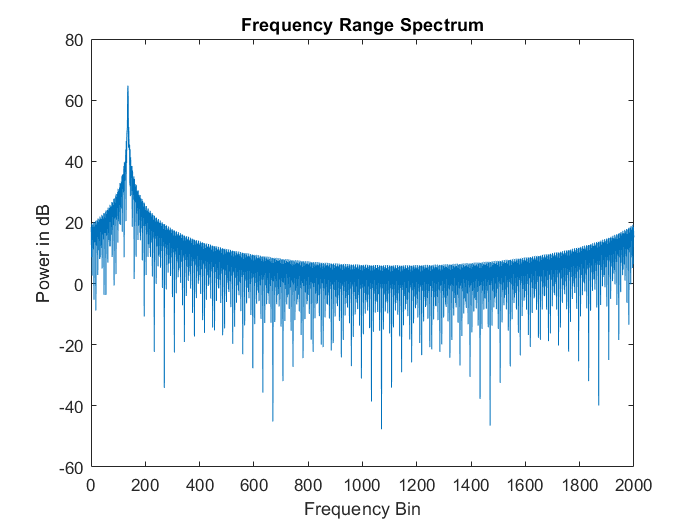

figure;
plot(Power_Test);
title('Frequency Range Spectrum');
xlabel('Frequency Bin');
ylabel('Power in dB');

**Shift Zero-Frequency Component To Center Of Spectrum**

X_Shift = fftshift(Matrix_Sum_Hori,2);                %Centering the FFT Since we can have "Positive" and "Negative" Frequencies

**Converting The Frequency Bins In Range **

Mag_X_Shift         = abs(X_Shift);
Frequency_bins      = 0:length(Mag_X_Shift(:,1))-1;                              
Frequency_Range     = Frequency_bins*Sampling_Frequency/length(Mag_X_Shift(:,1)); 
Range               = Frequency_Range*Chirp_Duration*c/(2*Bandwidth); 

**Converting The Frequency Bins in Velocity**

Frequency_Vel = (-Chirp_Repetition_Frequency/2:Chirp_Repetition_Frequency/Num_Of_Chirps:Chirp_Repetition_Frequency/2-Chirp_Repetition_Frequency/Num_Of_Chirps).*(-1);       %zero-centered frequency range
Velocity = Frequency_Vel*lambda/2.*(3600/1000);

**Plotting The Velocity Estimation **

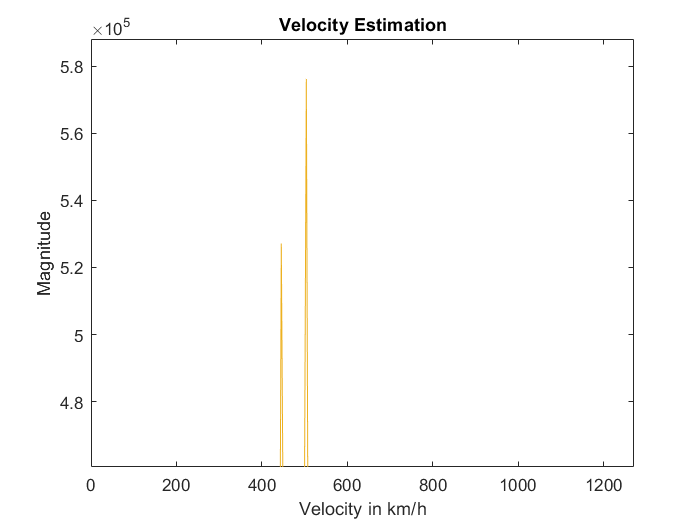

plot(Velocity,Mag_X_Shift);
title('Velocity Estimation');
xlabel('Velocity in km/h');
ylabel('Magnitude');

**Plotting the Range-Doppler-Image**

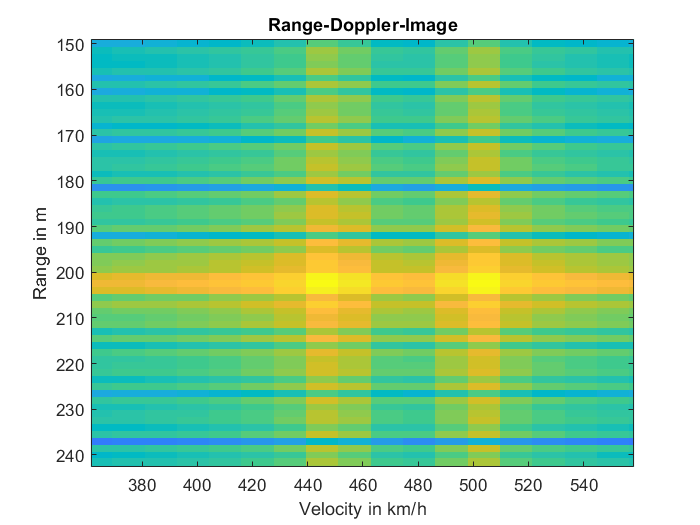

imagesc(Velocity,Range,100*log(1+Mag_X_Shift));
title('Range-Doppler-Image');
xlabel('Velocity in km/h');
ylabel('Range in m');

## Playing Instructions

Take a look one more time at the equations down below. 

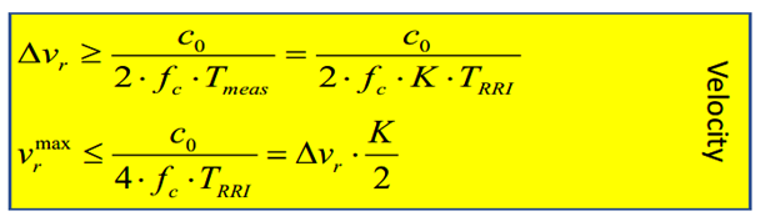

**Question**: How can I improve my Velocity Resolution?

**Now I want you to do the next as follows:**

    1.Setup the **same** **Velocity** for both of them (0 km/h) and with **different ranges** (target1 =100m and target2 = 200m). 

    2.Simulate and plot the Frequency response in 2d (Range-Doppler Image).

    3.Setup the **same Range** for both of them (200 m) and with **different velocities** (target1 = 500km/h and target2 = -250km/h). 

    4.Simulate and plot the Frequency response in 2d (Range-Doppler Image).

    5.Setup the **same Range** for both of them (200 m) and with **a** **different velocity of 50 km/h** (For Example: target1= 500km/h and target 2 = 450km/h). 

    6. Simulate and plot the Frequency response in 2d (Range-Doppler Image). (Make sure to zoom it)

    7.What is happening and what can we do to fix it?